# Generation of a quadratic one-dimensional mesh generation along line

It returns an one-dimensional quadratic three-noded mesh along a line:

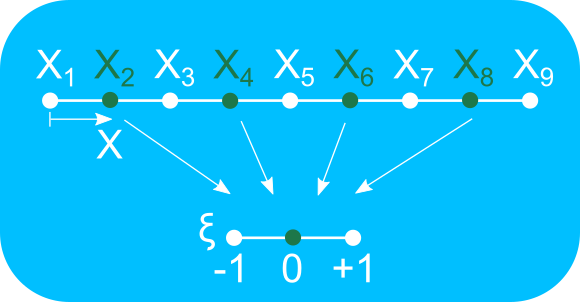

function msh = generateQuadraticMeshOnLine(mshL1)

## **Function Description**

Returns a structure containing the nodes and the elements on a line corresponding to an one-dimensional quadratic three-noded mesh based on an existing one-dimensional linear two-noded mesh.

**             Input :**

            `mshL1` : The one-dimensional linear mesh using two-noded elements as a structure with the following fields:

                            .nodes : Number of nodes in the one-dimensional mesh

                       .elements : Number of elements in the one-dimensional mesh

**          Output :**

                `msh` : The one-dimensional quadratic mesh using three-noded elements as a structure with the following fields:

                             .`nodes` : Number of nodes in the one-dimensional mesh

                       .`elements` : Number of elements in the one-dimensional mesh

## Function Implementation

### Input validation

    arguments
        mshL1 (1, 1) {mustHaveNodesAndElements}
    end

### Mesh generation

    msh.nodes = zeros(numel(mshL1.nodes(:, 1)) + numel(mshL1.elements(:, 1)), 1);
    msh.nodes(1:numel(mshL1.nodes(:, 1))) = mshL1.nodes(:, 1);
    for ii = 1:numel(mshL1.elements(:, 1))
        nodes_el_L1 = mshL1.nodes(mshL1.elements(ii, :));
        msh.nodes(numel(mshL1.nodes(:, 1)) + ii, 1) = mean(nodes_el_L1);
    end
    msh.elements = horzcat(mshL1.elements, transpose(numel(mshL1.nodes(:, 1)) + ...
        1:numel(mshL1.nodes(:, 1)) + numel(mshL1.elements(:, 1))));

end